# `datetime` Variables

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

manU = readtable("../data/manU.csv")

manU = 38×4 table
     GameTime     Place         Opponent          Points
    __________    _____    ___________________    ______

    17/05/2016    {'H'}    {'AFC Bournemouth'}      3   
           NaT    {'A'}    {'AFC Bournemouth'}      0   
    28/02/2016    {'H'}    {'Arsenal FC'     }      3   
    04/10/2015    {'A'}    {'Arsenal FC'     }      0   
           NaT    {'H'}    {'Aston Villa'    }      3   
           NaT    {'A'}    {'Aston Villa'    }      3   
           NaT    {'H'}    {'Chelsea FC'     }      1   
    07/02/2016    {'A'}    {'Chelsea FC'     }      1   
           NaT    {'H'}    {'Crystal Palace' }      3   
    31/10/2015    {'A'}    {'Crystal Palace' }      1   
           NaT    {'H'}    {'Everton FC'     }      3   
    17/10/2015    {'A'}    {'Everton FC'     }      3   
    01/05/2016    {'H'}    {'Leicester City' } 

manU(1:4, :)

ans = 4×4 table
     GameTime     Place         Opponent          Points
    __________    _____    ___________________    ______

    17/05/2016    {'H'}    {'AFC Bournemouth'}      3   
           NaT    {'A'}    {'AFC Bournemouth'}      0   
    28/02/2016    {'H'}    {'Arsenal FC'     }      3   
    04/10/2015    {'A'}    {'Arsenal FC'     }      0   


manU.GameTime(1:4)

ans = 4×1 datetime array
   17/05/2016
   NaT       
   28/02/2016
   04/10/2015


## Task 1

manU = sortrows(manU, "GameTime")

manU = 38×4 table
     GameTime     Place            Opponent            Points
    __________    _____    ________________________    ______

    12/09/2015    {'H'}    {'Liverpool FC'        }      3   
    20/09/2015    {'A'}    {'Southampton FC'      }      3   
    26/09/2015    {'H'}    {'Sunderland AFC'      }      3   
    04/10/2015    {'A'}    {'Arsenal FC'          }      0   
    17/10/2015    {'A'}    {'Everton FC'          }      3   
    25/10/2015    {'H'}    {'Manchester City'     }      1   
    31/10/2015    {'A'}    {'Crystal Palace'      }      1   
    07/11/2015    {'H'}    {'West Bromwich Albion'}      3   
    21/11/2015    {'A'}    {'Watford FC'          }      3   
    28/11/2015    {'A'}    {'Leicester City'      }      1   
    02/02/2016    {'H'}    {'Stoke City'          }      3   
    07/02/2016    {'A'}    {'Chelsea FC

## Task 2

ptsTot = cumsum(manU.Points)

ptsTot =      3
     6
     9
     9
    12
    13
    14
    17
    20
    21


## Task 3

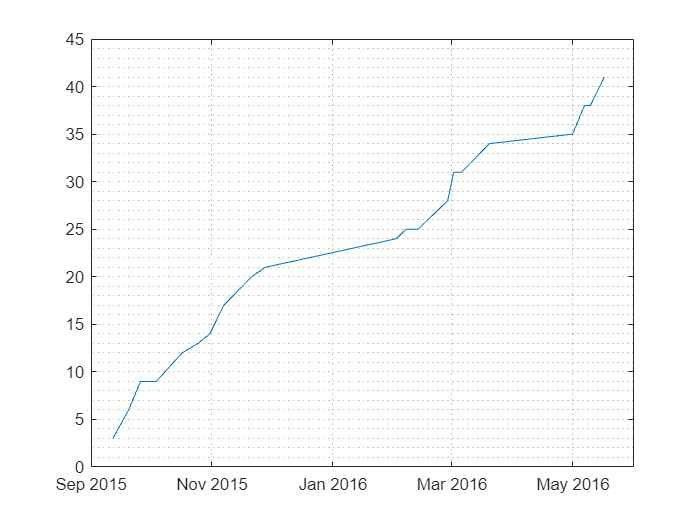

plot(manU.GameTime, ptsTot)
grid minor